# Country Visualization

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 12/2020

Description: Plot a country sustainability for a specific year

clc
clear 
close all

## Load Data

load ../Data/Data_Indicators.mat 
load ../Data/Data_EIA_H.mat


%% Variables

% Select a specific year
year=2015;
index=year-1989;

% Labels
Labels=strtrim(Data_EIA_H.Labels);

CO2_N=Indicators.GHG_N(:,index);
Exp_N=Indicators.Exp_N(:,index);
GDP_N=Indicators.GDP_N(:,index);
HDI_N=Indicators.HDI_N(:,index);
Land_N=Indicators.Land_N(:,index);
Mat_N=Indicators.Mat_N(:,index);
Ren_N=Indicators.Ren_N(:,index);
Water_N=Indicators.Water_N(:,index);

% Change the number to get a different country
% Check Labels for reference
n=27;
Country=Labels(n)

Country = 1×1 cell array
    {'Brazil'}



X=[0,45,90,135,180,225,270,315,360]*pi/180;

% Optimum
Y=[GDP_N(n),CO2_N(n),Exp_N(n),Ren_N(n),Water_N(n),Land_N(n),Mat_N(n),HDI_N(n),GDP_N(n)];
[x,y] = pol2cart(X,Y);
Area(n)=polyarea(x,y);
y2=ones(1,9);

% Octagon
[x2,y2] = pol2cart(X,y2);

## Figure

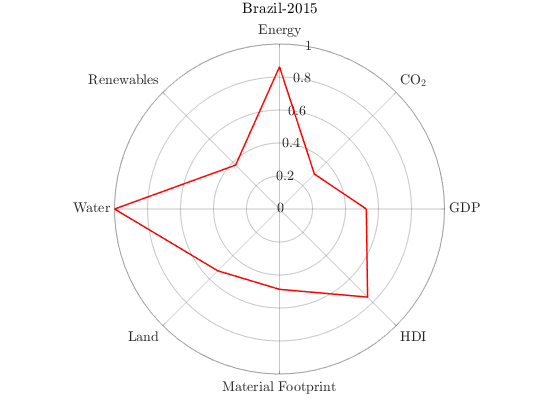

figure
 Values=Y;
    X=[0,45,90,135,180,225,270,315,360]*pi/180;

    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color','r','linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    title(append(Country,string(-year)),'Interpreter',"latex")

filename=append(char(Country),string(-year), '.png');
% print('-dpng','-r400',filename)